## Addition of Variable Vertical Diffusion to a Model of Phytoplankton Vertical Distribution

**Summary of Findings and Changes**

## Speed Improvements

The maxim "first make it right, then make it fast" is a good one, but limited early optimization can save time.

- Some basic operations were done in for loops rather than as vectors.  I made the changes, speeding up the code by 10x or more.  This will mean less waiting during testing.

- The GUI is nice, but slow compare to just running code.  I made a simple script to bypass the GUI, with the intent or restoring it later.

- Side note: building a "mex" executable could be a big speed (and possibly memory) win if simulations become large and slow.

## Random walk bias

I noticed that the random walk was either 1 unit up or down, when it seems that a continuous distribution might make more sense.  The first paper I found (Visser 1997) points out a common error which leads to biased migration of particles toward areas of low diffusion.  We have that problem!  Running with a drop in diffusivity by a factor of 4 at 50 meters, this uneven distribution is obtained after 4 hours:

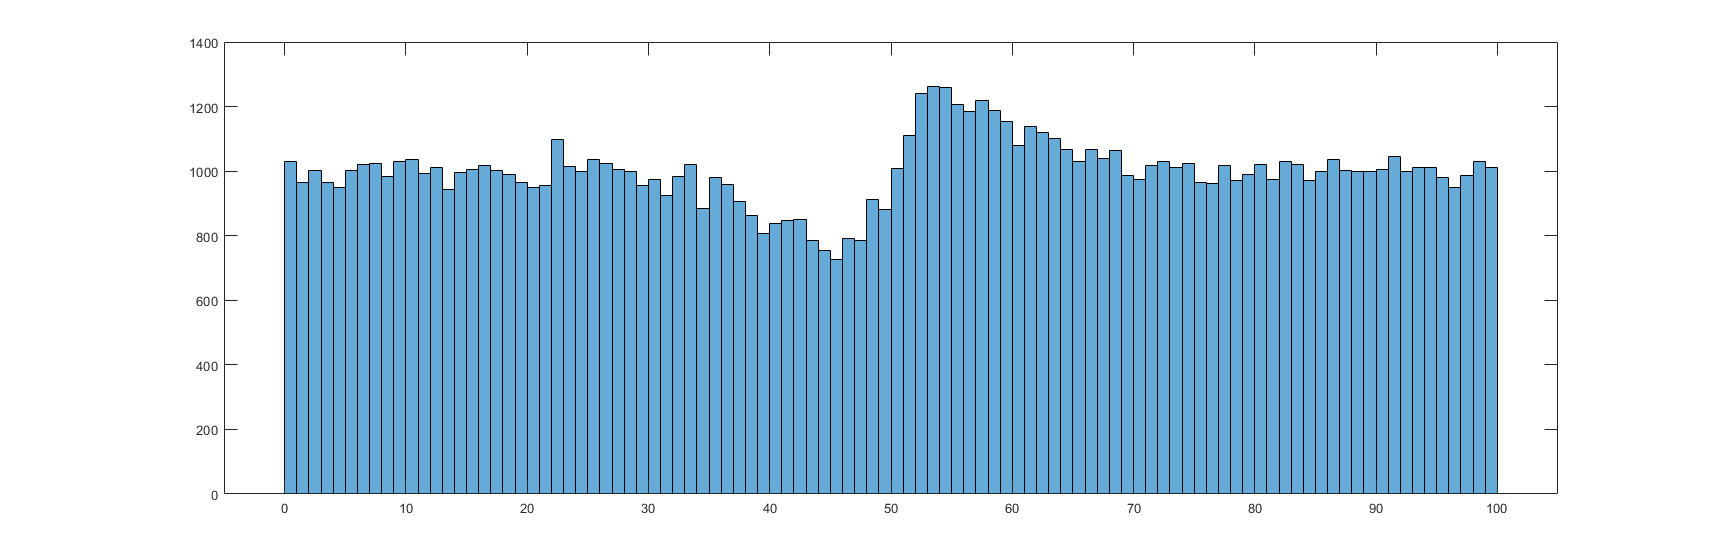

openfig('figures/Biased_Diffusion.fig');

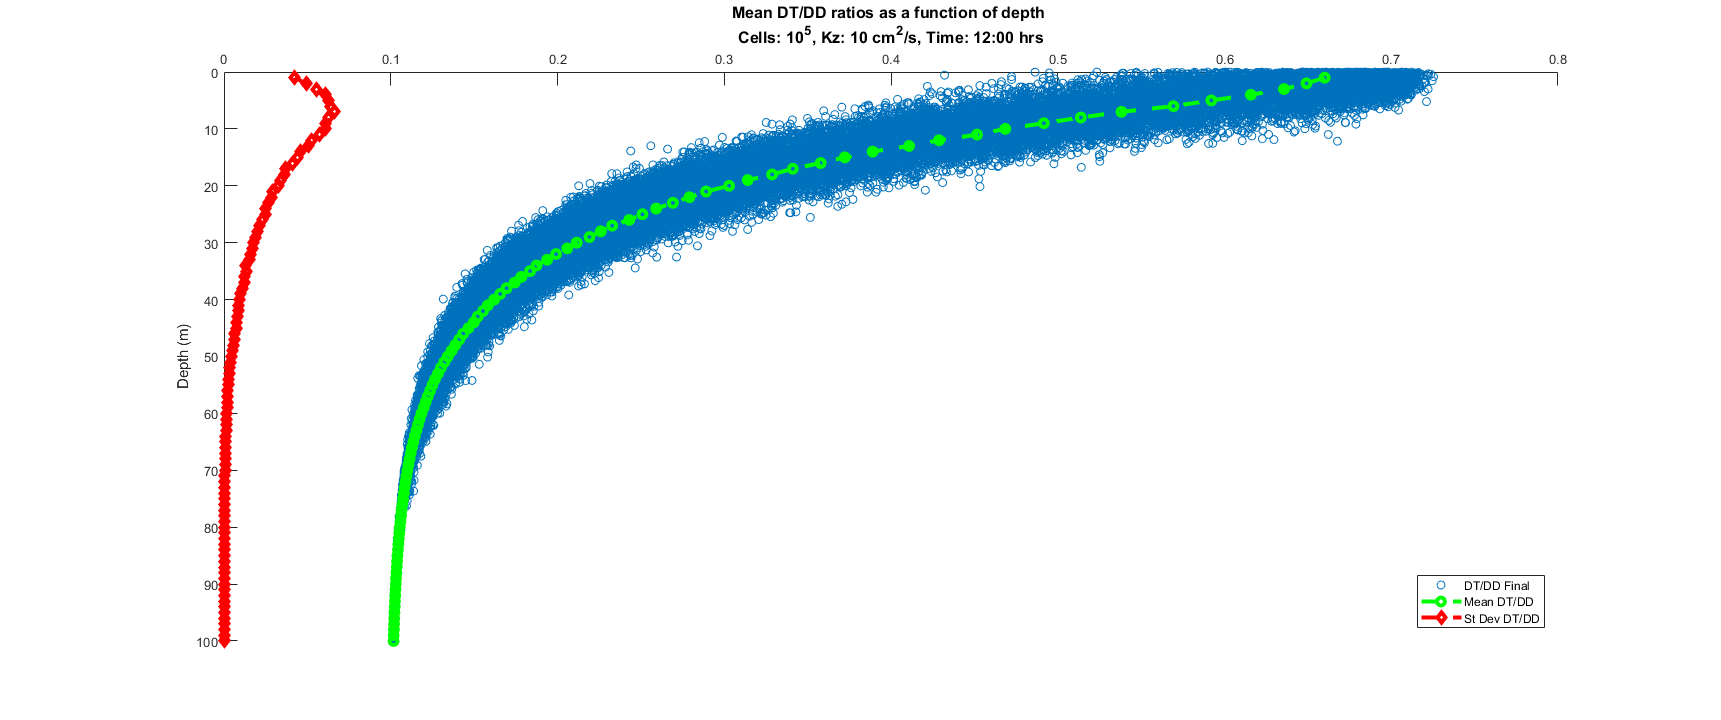

openfig('figures/Biased_DTDD.fig');

The function in the original version uses the code 

`sqrt(2*dt*Kz)`

Representing a step size of

 $\pm \sqrt{2K\delta t}$  where the sign is chosen randomly.

Visser (1997) equation 3 shows

$R\sqrt{\frac{2}{r}K\delta t}$  where R is random and r is the standard deviation of R.

however Visser points out that this leads to a bias when K is not constant, recommending (equation 6)

$\mathrm{K'}\left(z\right)\delta t+R\sqrt{\left\lbrace \frac{2}{r}K\left\lbrack z+\frac{1}{2}\mathrm{K'}\left(z\right)\delta t\right\rbrack \delta t\right\rbrace }$ where $\mathrm{K'}=\frac{\delta K}{\delta z}$

BUT the square brackets are meant to imply that K is a function of the contents, not normal mathematical grouping!

Examples in the paper use a uniform distribution from -1 to 1 for R, not a normal distribution, so I will do the same.  The standard deviation is then $\sqrt{\frac{1}{3}}$.

## Initial attempts at bias removal

After implementing the equations above, I found that there was still a distribution bias, but in the opposite direction.  I tried a several approaches to fix this.

I noticed that Visser and papers referencing it uses a limited time step based on the second derivative of the diffusion coefficient (dt << min(1/K'')).  I used the absolute value of K'' here, which is not specified by Visser (1997) or in North (2006), but it is necessary.   Reducing the time step was not every effective, and would have required substantial changes to implement due to memory limitations.  Nevertheless, it is probably a good idea to keep the required timestep large by not setting up a large second derivative on the Kz distribution.

Thinking that I may have misunderstood some of Visser's notation or changed a sign (his depths are negative, ours are positive) I tried changing signs on various terms.  This was not an improvement, but I noticed that the Kz' term in the diffusion step calculation reversed the direction of the bias.  Empirically, I found that** multiplying the term by 0.6 eliminates the bias** (Depth Array, wA variable).

Below are some examples from this process.

A repeat of the effect of the original approach:

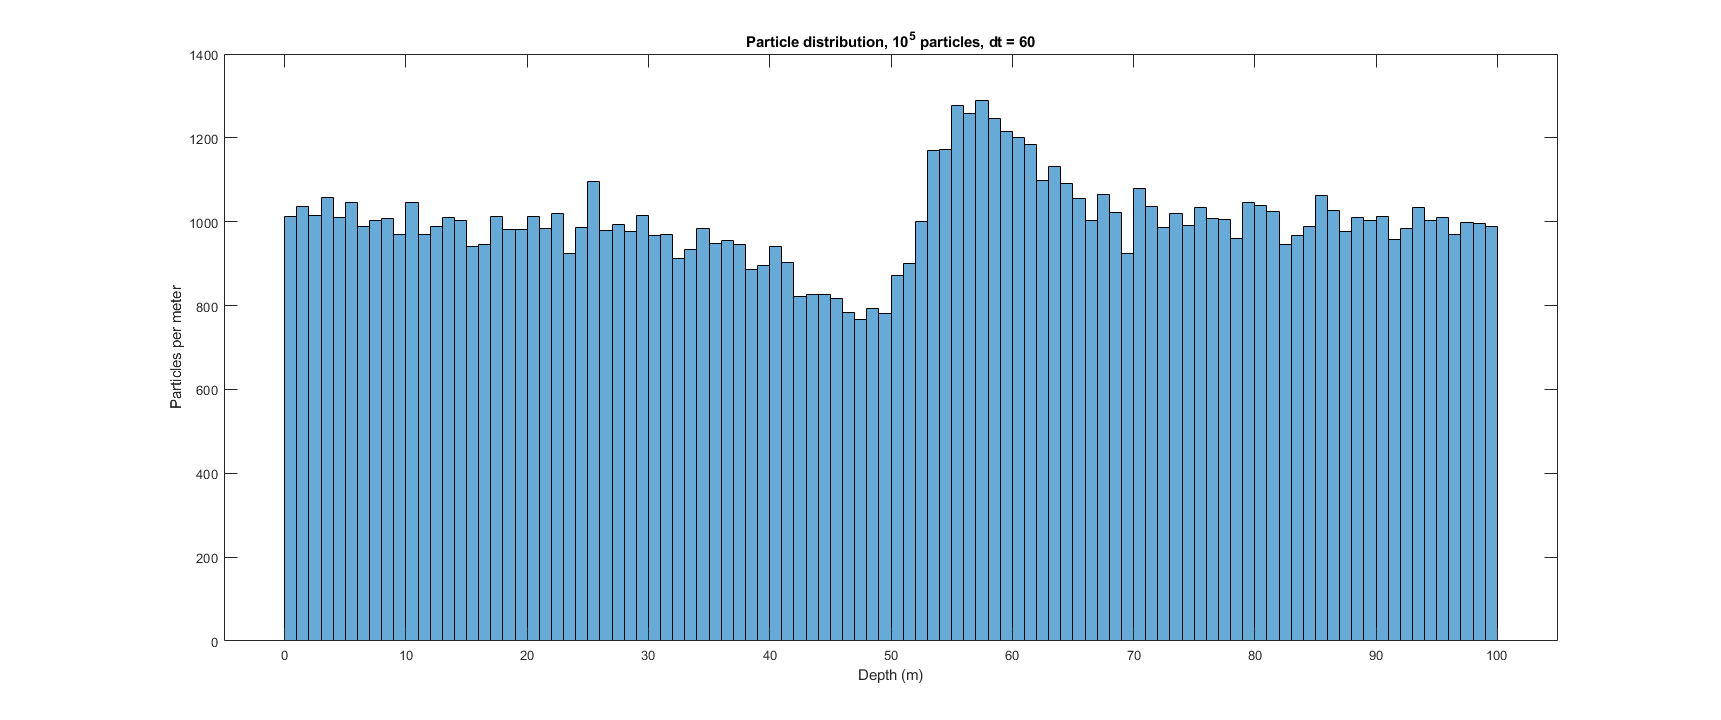

openfig('figures/Original_Diffusion_n5_dt60.fig');

Initial implementation of Visser equation 6, with the original 60-second timestep:

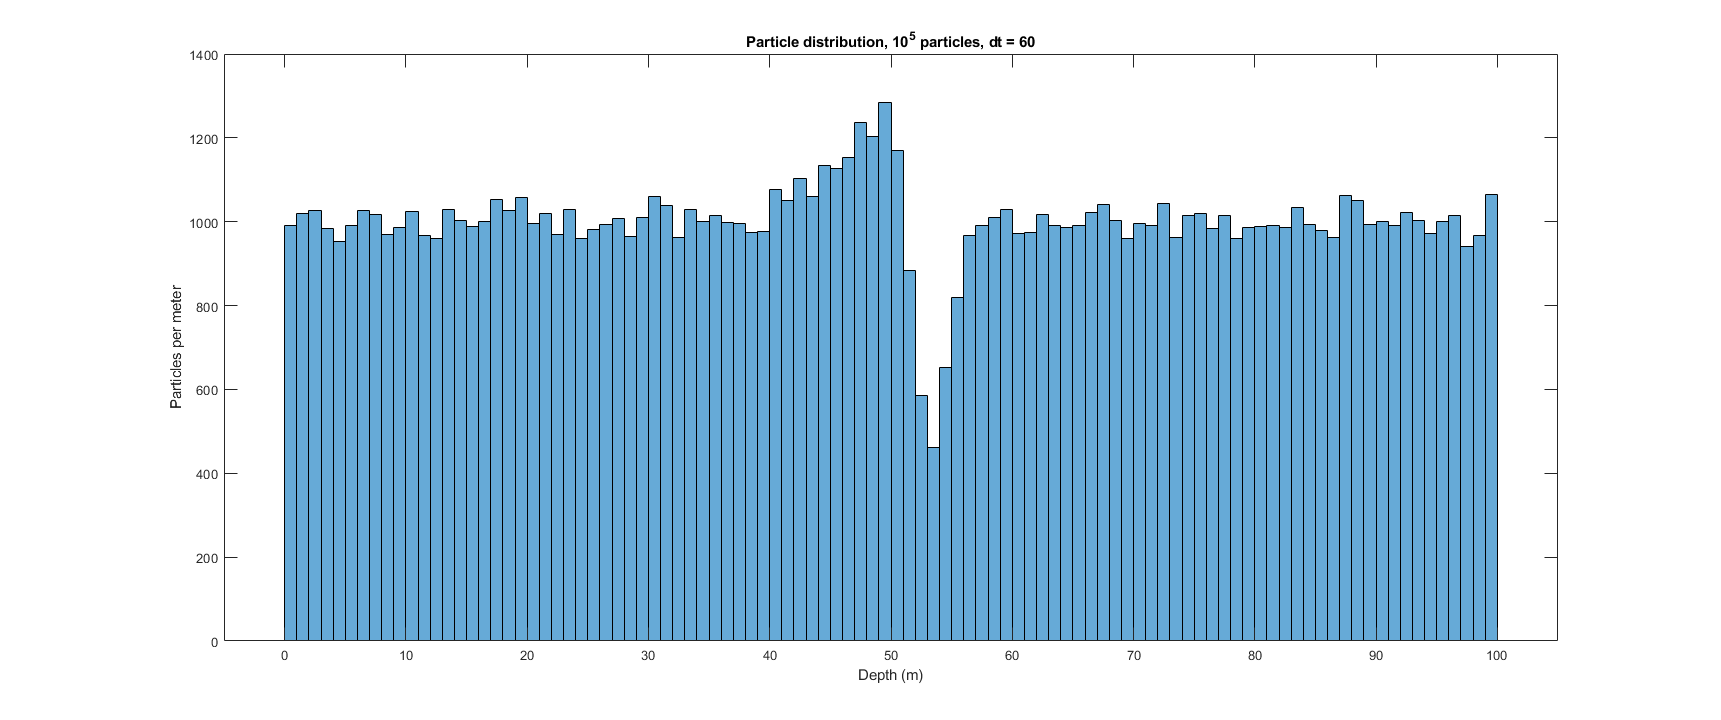

openfig('figures/Visser_Diffusion_n5_dt60.fig');

The same implementation with a timestep of 6 seconds (little change):

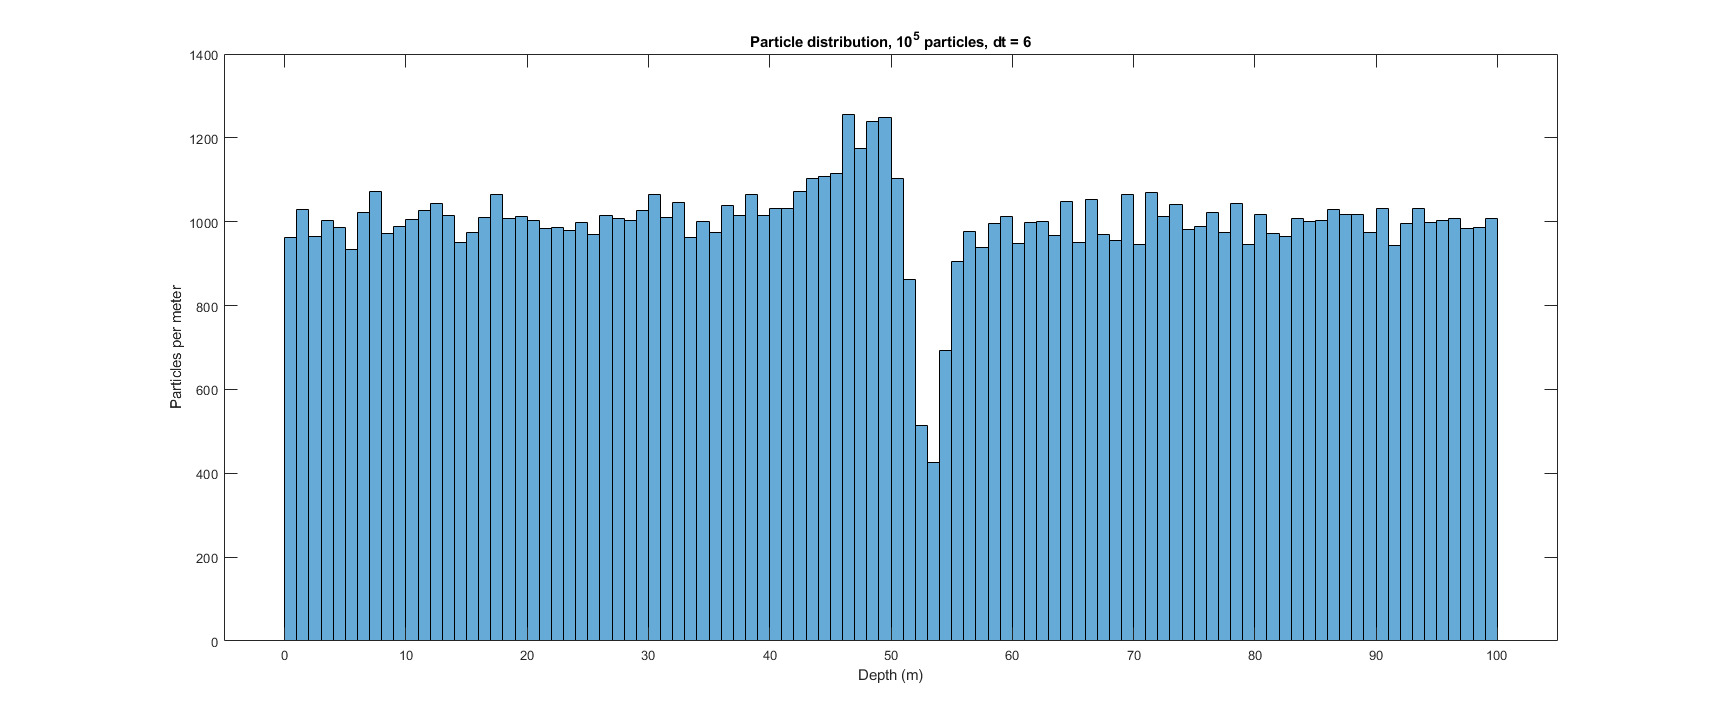

openfig('figures/Visser_Diffusion_n5_dt6.fig');

My change which multiplies the first term from Visser by 0.6:

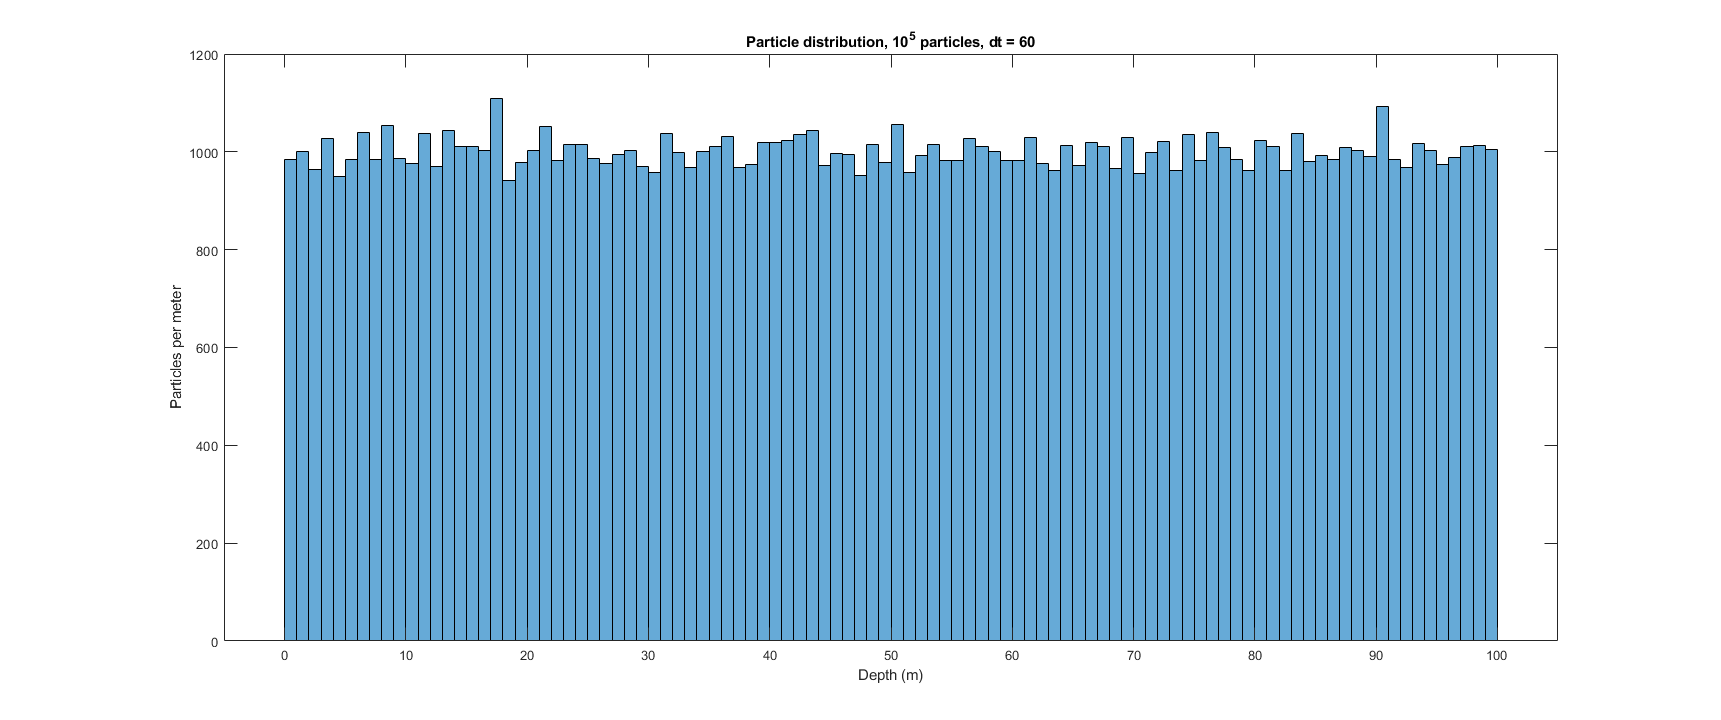

openfig('figures/Ryan_Diffusion_n5_dt60.fig');

Finally, here is the DT/DD figure based on the updated model:

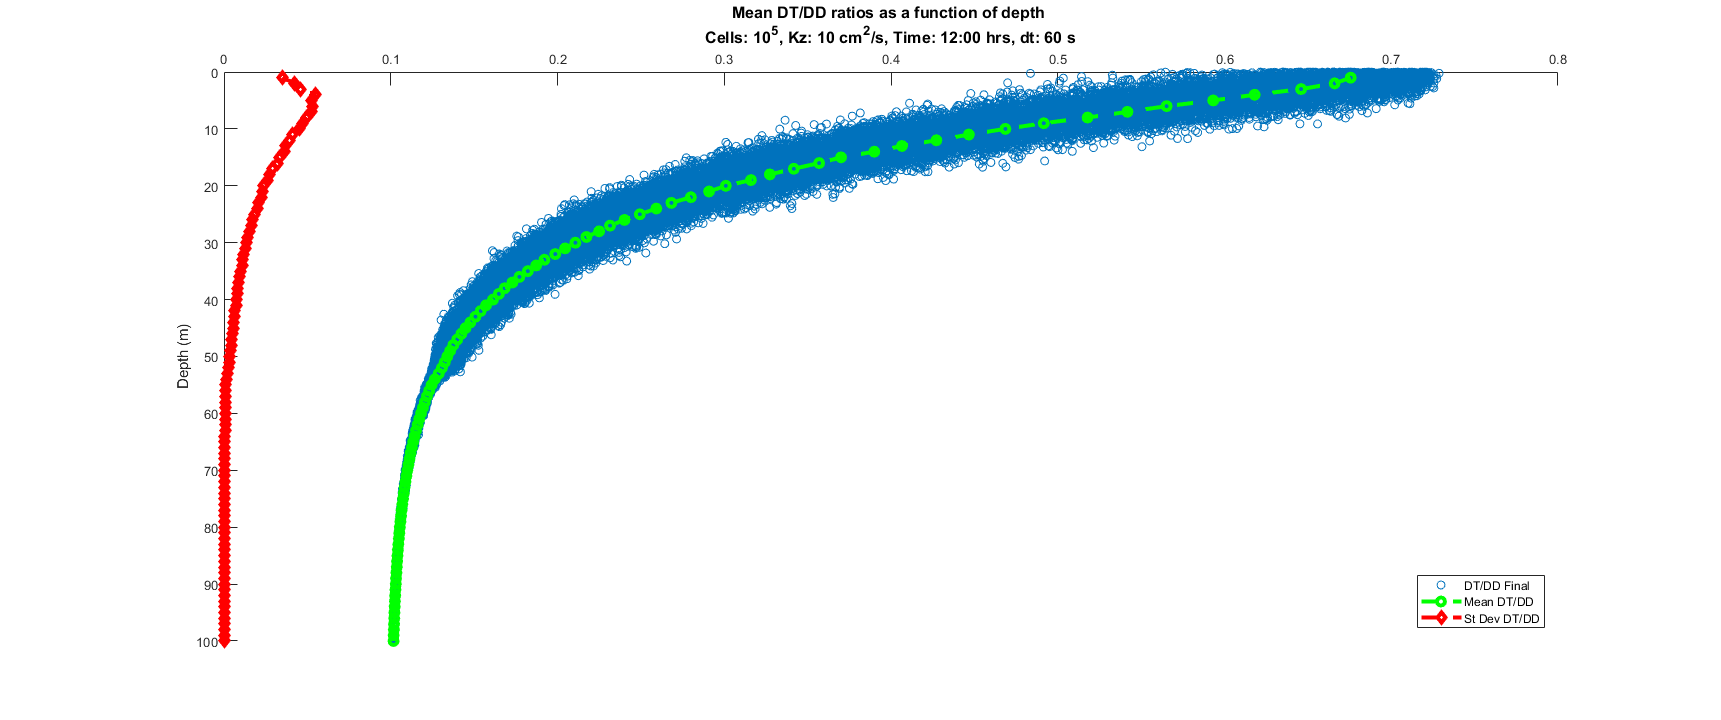

openfig('figures/Ryan_Diffusion_n5_dt60_DTDD.fig');

Note that the points are more tightly grouped now, probably a result of using a distribution of step sizes rather than just -1 and 1.  **This needs to be check to seen which scaling is more accurate.**

## Adding the Thermocline

Measured profiles of eddy diffusion are hard to come by, but there are several pieces of information available.

- ${10}^{-2}$ $m^2/s$ is a large value, suitable for the mixed layer

- Mixing is constrained at surfaces (air and substrate) and by strong density gradients (pycnocline)

- ${10}^{-4}$ $m^2/s$ is a low value

There are also some modeling-related factors.

- Stability of the solution is affected by the second derivative of the diffusion value.  Large values can be a problem, so distributions with hard corners are a problem.

- There is a tradeoff between interpolation functions that stay close to the input values, and those that create a smoother curve.  I have chosen Matlab's "Makima" interpolation option.

The Kz distribution entered in cm^2/s to be consistent with the original Matlab script.  The current default is:

Depth     0    10    85    95   100   105   115   200  [m]

Kz       10   100   100   1.5   1      1.5     10     10  [cm^2/s]

   Resulting in this distribution

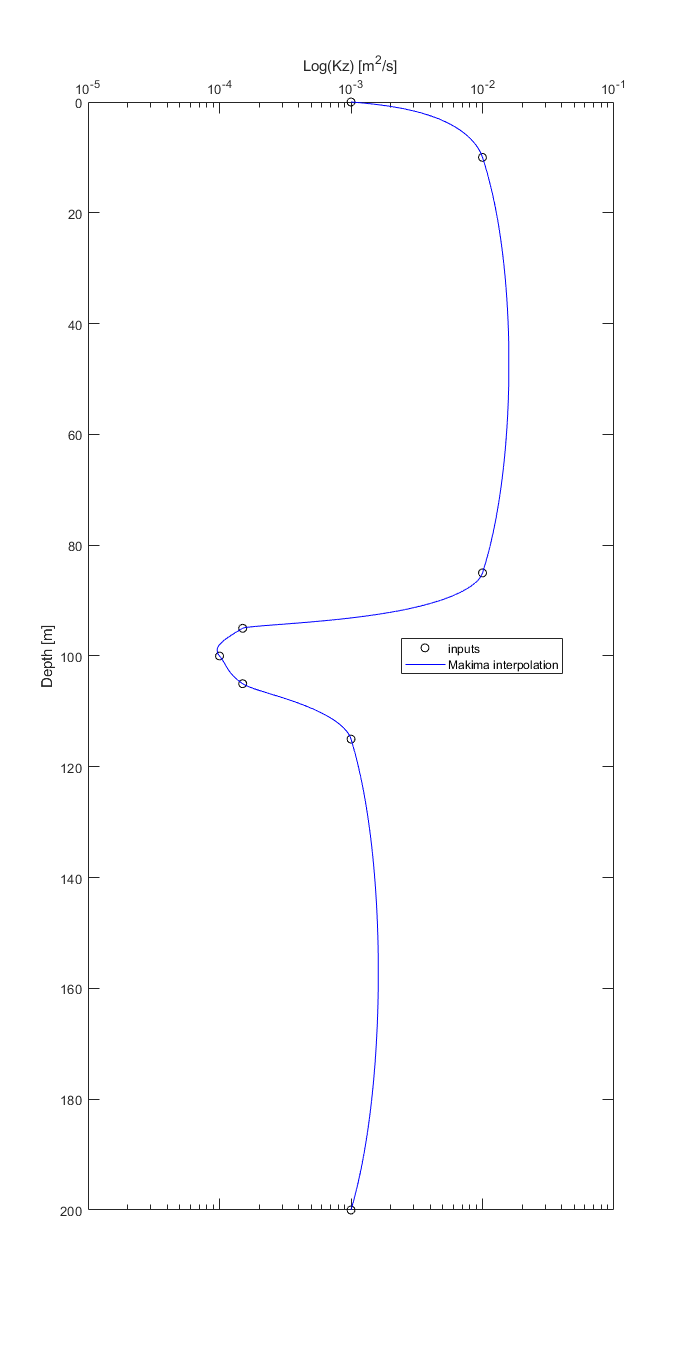

openfig('figures/Kz_distribution.fig');

## One way of looking at the effect of this distribution is to plot the final location of particles after 12 hours of diffusion, versus their original locations.  

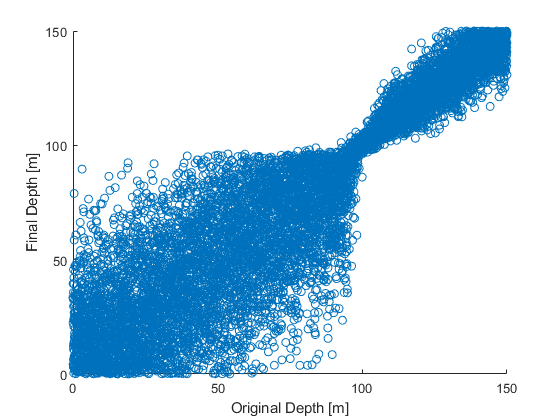

openfig('figures/DepthScatterN4.fig');

## References

North, E. W., Hood, R. R., Chao, S. Y. & Sanford, L. P. Using a random displacement model to simulate turbulent particle motion in a baroclinic frontal zone: A new implementation scheme and model performance tests. *J. Mar. Syst.* **60,** 365–380 (2006).

Visser, A. Using random walk models to simulate the vertical distribution of particles in a turbulent water column. *Mar. Ecol. Prog. Ser.* **158,** 275–281 (1997).